addpath 'E:\MATLAB'
addpath 'E:\MATLAB'\'IMAGE SETS'\
addpath 'E:\MATLAB\COMPARISON\ngocho\'

ImageNames={'aerial1.tiff';'aerial2.tiff';'aerial3.tiff';'aerial4.tiff';'aerial5.tiff';'aerial6.tiff';'aerial7.tiff';'aerial8.tiff';'airplane.png';'arctichare.png';'girl.png';'lena.png';'monarch.png';'peppers1.tiff';'peppers2.png';'tulips.png'};
PSNR_R=zeros(size(ImageNames,1),1);
PSNR_G=zeros(size(ImageNames,1),1);
PSNR_B=zeros(size(ImageNames,1),1);
SSIM_R=zeros(size(ImageNames,1),1);
SSIM_G=zeros(size(ImageNames,1),1);
SSIM_B=zeros(size(ImageNames,1),1);
PSNR_Colour=zeros(size(ImageNames,1),1);
SSIM_Colour=zeros(size(ImageNames,1),1);
NIQE_Colour=zeros(size(ImageNames,1),1);
tic
tic
for i=1:size(ImageNames,1)
    string=char(ImageNames(i));
    A=imread(string);
    R=A(:,:,1);
    G=A(:,:,2);
    B=A(:,:,3);
    LR=double(bmn_decimation(R));
    LRG=double(bmn_decimation(G));
    LRB=double(bmn_decimation(B));
    [SR,SRG,SRB]=bmn_wavelet_SR_LoG1_51(LR,LRG,LRB);
    SRimage=cat(3,uint8(SR),uint8(SRG),uint8(SRB));
    PSNR_R(i)=psnr(uint8(SR),uint8(R));
    PSNR_G(i)=psnr(uint8(SRG),uint8(G));
    PSNR_B(i)=psnr(uint8(SRB),uint8(B));
    SSIM_R(i)=ssim(uint8(SR),uint8(R));
    SSIM_G(i)=ssim(uint8(SRG),uint8(G));
    SSIM_B(i)=ssim(uint8(SRB),uint8(B));
    PSNR_Colour(i)=psnr(SRimage,A);
    SSIM_Colour(i)=ssim(SRimage,A);
    NIQE_Colour(i)=niqe(SRimage);
end
toc

Elapsed time is 28.685982 seconds.


T=table(ImageNames,PSNR_R,PSNR_G,PSNR_B,SSIM_R,SSIM_G,SSIM_B, ...
    PSNR_Colour,SSIM_Colour,NIQE_Colour)

T = 16×10 table
        ImageNames        PSNR_R    PSNR_G    PSNR_B    SSIM_R     SSIM_G     SSIM_B     PSNR_Colour    SSIM_Colour    NIQE_Colour
    __________________    ______    ______    ______    _______    _______    _______    ___________    ___________    ___________

    {'aerial1.tiff'  }    30.393    17.772    17.822    0.76551    0.75981    0.81339       19.44         0.76538        5.7974   
    {'aerial2.tiff'  }    32.468    24.013    24.163    0.87099    0.74703    0.79893      25.544         0.84267        5.7221   
    {'aerial3.tiff'  }     27.77    17.373    17.558    0.82208    0.60888    0.70227      19.028         0.63857      

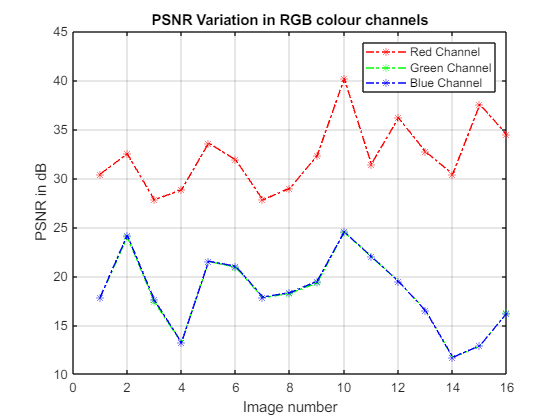

Table_location='E:\MATLAB\Results';
path_format = [Table_location '\NGOCHOColourImages.xlsx'];
writetable(T,path_format)
n=1:size(ImageNames,1);
figure;
plot(n,PSNR_R,'-.r*',n,PSNR_G,'-.g*',n,PSNR_B,'-.b*')
grid on
ylabel ('PSNR in dB')
xlabel ('Image number')
title ('PSNR Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel')

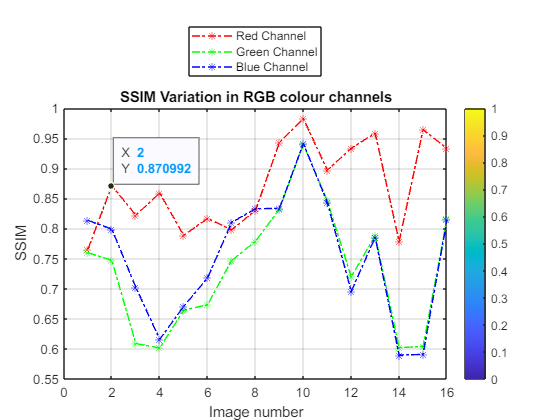

figure;
plot(n,SSIM_R,'-.r*',n,SSIM_G,'-.g*',n,SSIM_B,'-.b*')
grid on
ylabel ('SSIM')
xlabel ('Image number')
title ('SSIM Variation in RGB colour channels','FontWeight','bold');
legend('Red Channel','Green Channel','Blue Channel', ...
    'Location','northoutside')

colorbar
ax = gca;
chart = ax.Children(3);
datatip(chart,2,0.871);

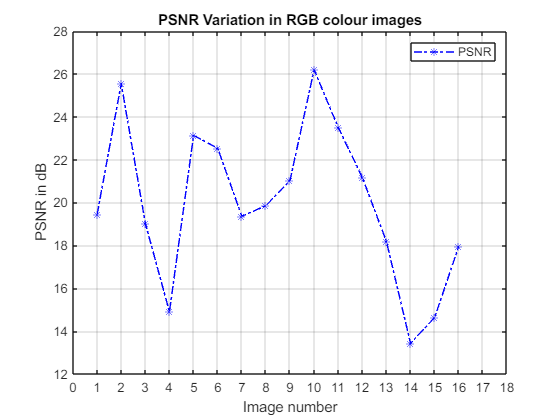

figure;
plot(n,PSNR_Colour','-.b*')
xlim([0 18]);
xticks(0:18);
grid on
ylabel ('PSNR in dB')
xlabel ('Image number')
title ('PSNR Variation in RGB colour images','FontWeight','bold');
legend('PSNR')

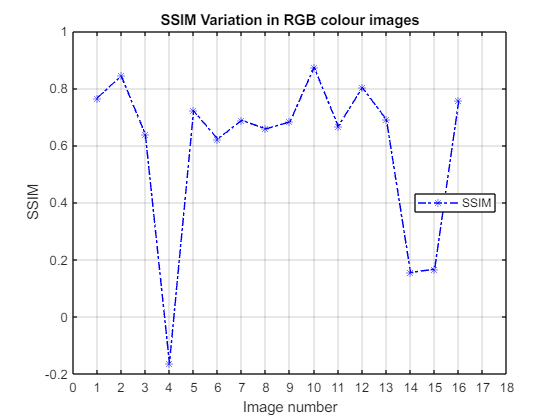

figure;
plot(n,SSIM_Colour,'-.b*')
xlim([0 18]);
xticks(0:18);
grid on
ylabel ('SSIM')
xlabel ('Image number')
title ('SSIM Variation in RGB colour images','FontWeight','bold');
legend('SSIM','Location',"east")

function [SR,SRG,SRB]=bmn_wavelet_SR_LoG1_51(LR,LRB,LRG)
%This function carries out single image super-resolution. The input low
%resolution image is used as the low frequency approximation image. High
%frequency detail sub-bands are estimated by wavelet decomposition of a
%bicubic expansion of the inpout LR image. The initial super resolution
%image is further improved by back-projection using 5 x 5 LoG filter
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %
% Author: Boniface M. Ngocho %
% School of Engineering %
% University of Nairobi %
% 12th November 2015 %
% e-mail:bmnngocho@yahoo.co.uk %
% %
%%%%%%%%%%%%%%%%%%%%%%%%%%%
GT2=bmn_bicubic(LR,2); % Enlarge LR image using bicubic interpolation
GT2G=bmn_bicubic(LRG,2);
GT2B=bmn_bicubic(LRB,2);
[~,H,V,D]=dwt2(GT2,'haar'); % DWT multiresolution
[~,HG,VG,DG]=dwt2(GT2G,'haar');
[~,HB,VB,DB]=dwt2(GT2B,'haar');
LR0=2.*double(LR); % Scale LR pixels
LR0G=2.*double(LRG);
LR0B=2.*double(LRB);
SR0=(idwt2(LR0,H,V,D,'haar')); %IDWT reconstruction
SR0G=(idwt2(LR0G,HG,VG,DG,'haar'));
SR0B=(idwt2(LR0B,HB,VB,DB,'haar'));
% Define back-projection filter
k=0.11;
b=-0.25; c=-2; d=-0.25;
a=1-(4*(b+c+d));
h1=[d 0 0 0 d;0 b c b 0;0 c a c 0;0 b c b 0;d 0 0 0 d];
h=k.*h1;
%Back Projection (3 steps)
[M,N]=size(LR);
Z=zeros(M,N);
SRin=SR0;
SRinG=SR0G;
SRinB=SR0B;
 for j=1:3
 LR1=bmn_decimation(SRin); %Calculate new LR image
 LR1G=bmn_decimation(SRinG);
 LR1B=bmn_decimation(SRinB);
 E1=LR-LR1; %Evaluate image error
 E1G=LRG-LR1G;
 E1B=LRB-LR1B;
 E11=imfilter(E1,h);
 E11G=imfilter(E1G,h);
 E11B=imfilter(E1B,h);
 E11=(double(E11)).*2;
 E11G=(double(E11G)).*2;
 E11B=(double(E11B)).*2;
 BP1=idwt2(E11,Z,Z,Z,'haar'); %Error Super Resolution
 BP1G=idwt2(E11G,Z,Z,Z,'haar');
 BP1B=idwt2(E11B,Z,Z,Z,'haar');
 SR1=SRin+BP1;
 SR1G=SRinG+BP1G;
 SR1B=SRinB+BP1B;
 SRin=SR1;
 SRinG=SR1G;
 SRinB=SR1B;
 end
SR=uint8(SRin);
SRG=uint8(SRinG);
SRB=uint8(SRinB);
end
